%read in data 
O = readtable("customeroveralldata",'TreatAsEmpty',{'"'});

C=readtable("custfunnel"); 

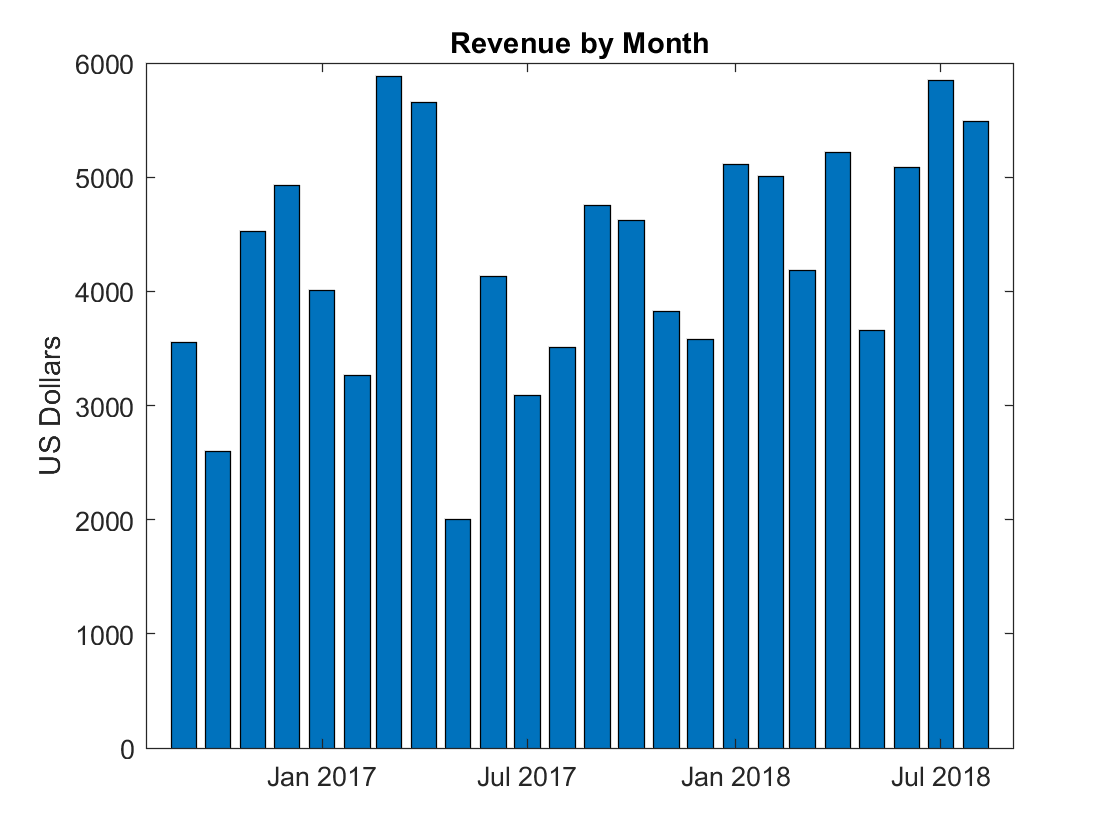

%find revenue by month and plot it
[totalrev, year_month] = groupsummary(C.RevenueGenerated, C.year_month, @sum);
dts=datetime(year_month,'InputFormat','MM-yyyy');
[dns,sidx] = sort(dts); 
orderedRev=totalrev(sidx); 
figure(1) 
bar(dns,orderedRev)
title("Revenue by Month")
ylabel("US Dollars")

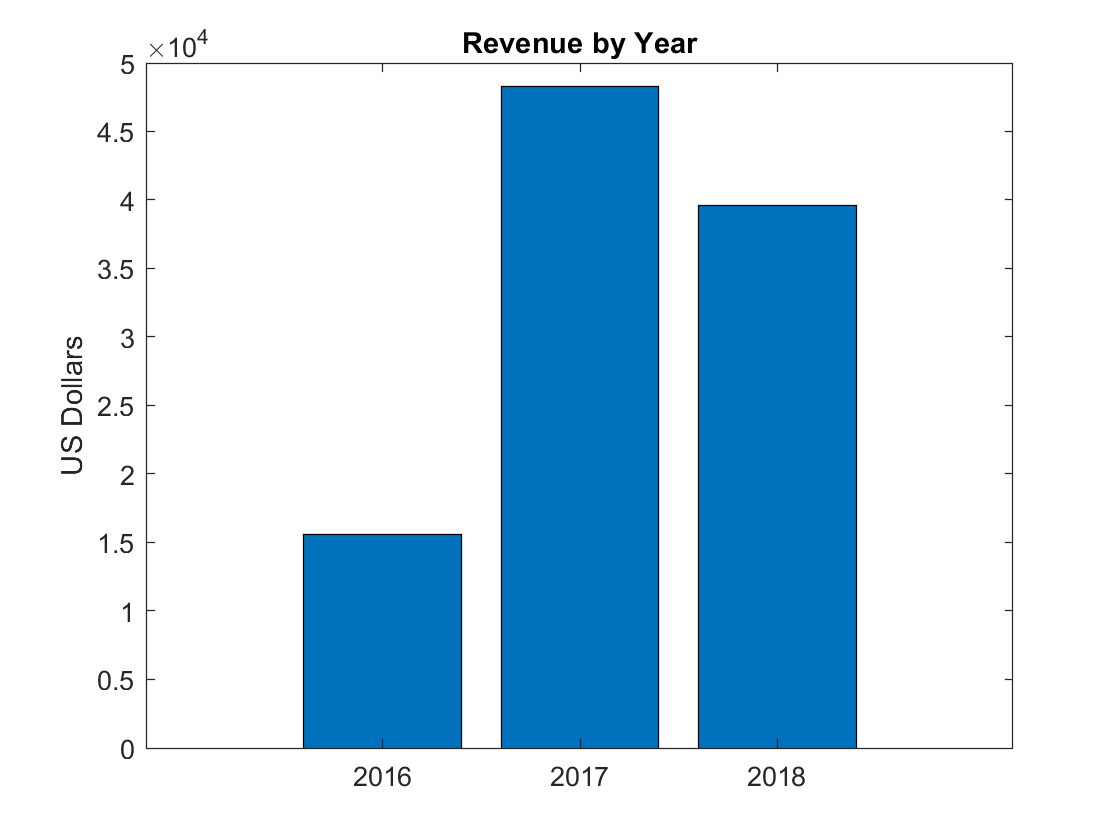

%find revenue by year and plot it 
[totalrev, year] = groupsummary(C.RevenueGenerated, C.year, @sum);
figure(2)
bar(year,totalrev)
title("Revenue by Year")
ylabel("US Dollars")

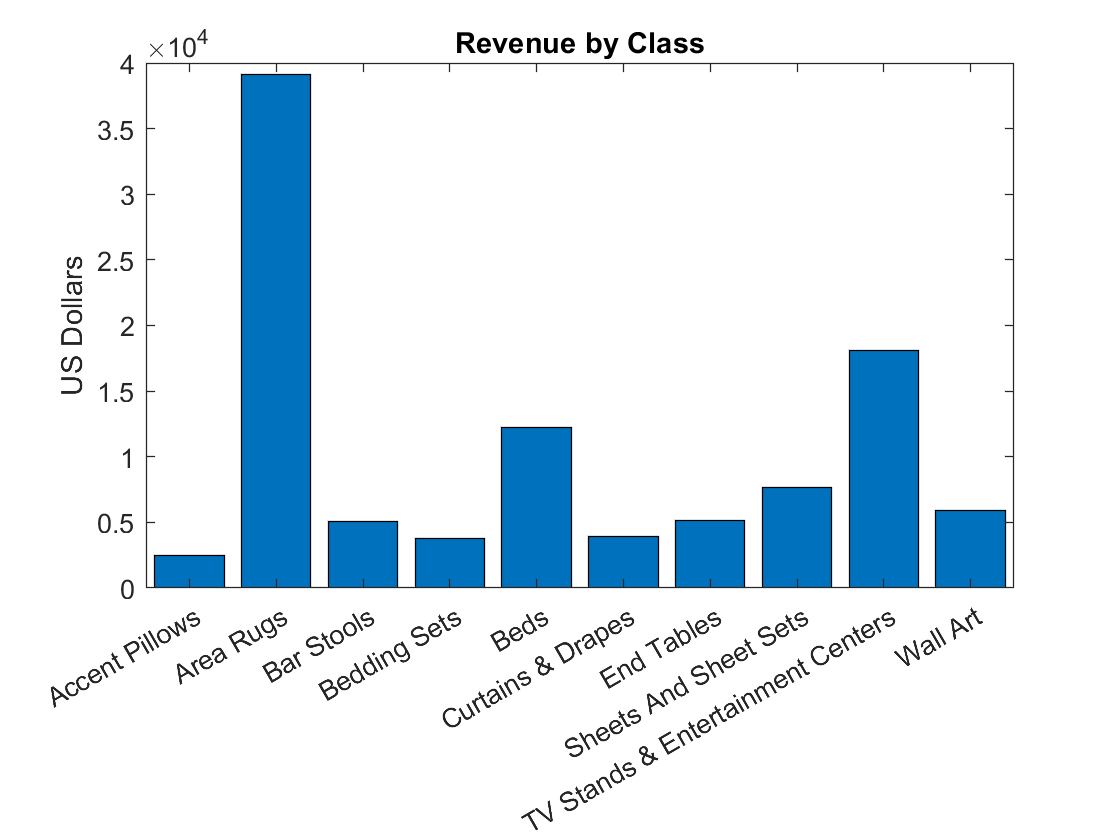

%find revenue by class and plot it 
[rev, class] = groupsummary(C.RevenueGenerated, C.className, @sum);
figure(3)
bar(categorical(class),rev);
title("Revenue by Class")
ylabel("US Dollars")

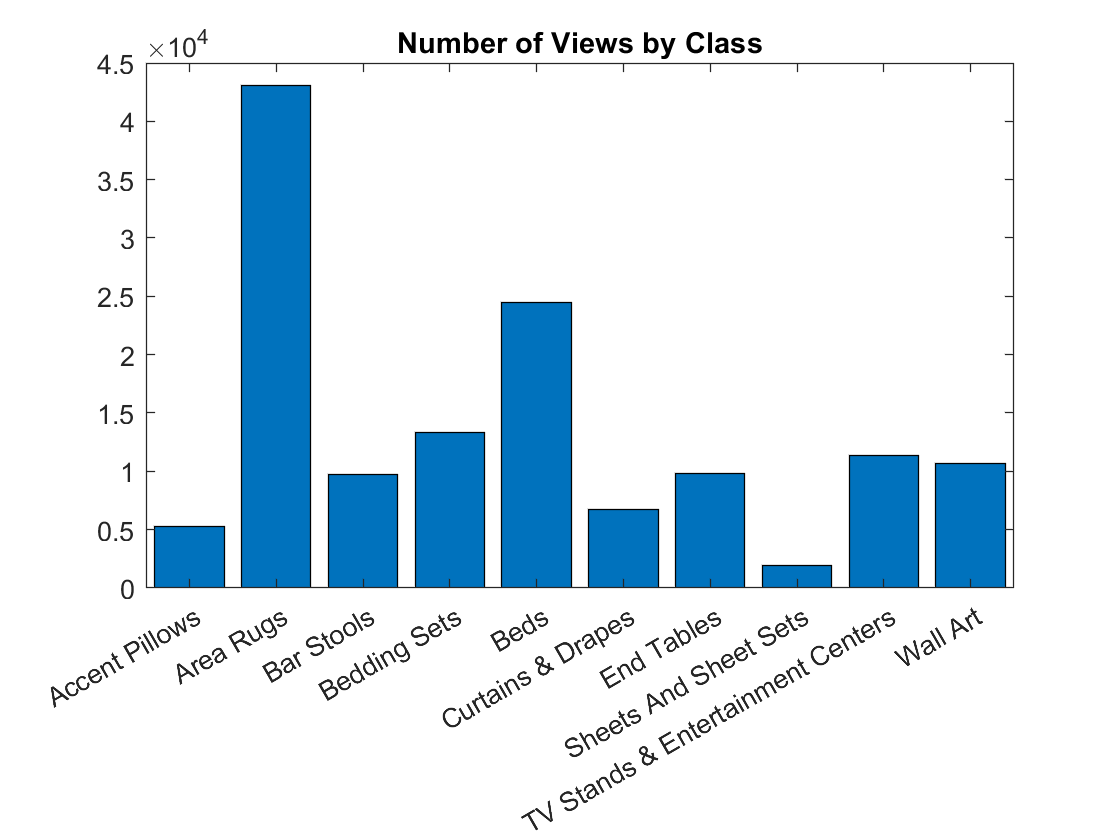

%find sku view, add,buy revenue vs class 
[view, class1] = groupsummary(C.skusViewed, C.className, @sum);
[add, class2] = groupsummary(C.skusAddedToCart, C.className, @sum);
[buy, class3] = groupsummary(C.skusPurchased, C.className, @sum);
class1=categorical(class1); 
figure(4)
bar(class1,view);
title("Number of Views by Class");

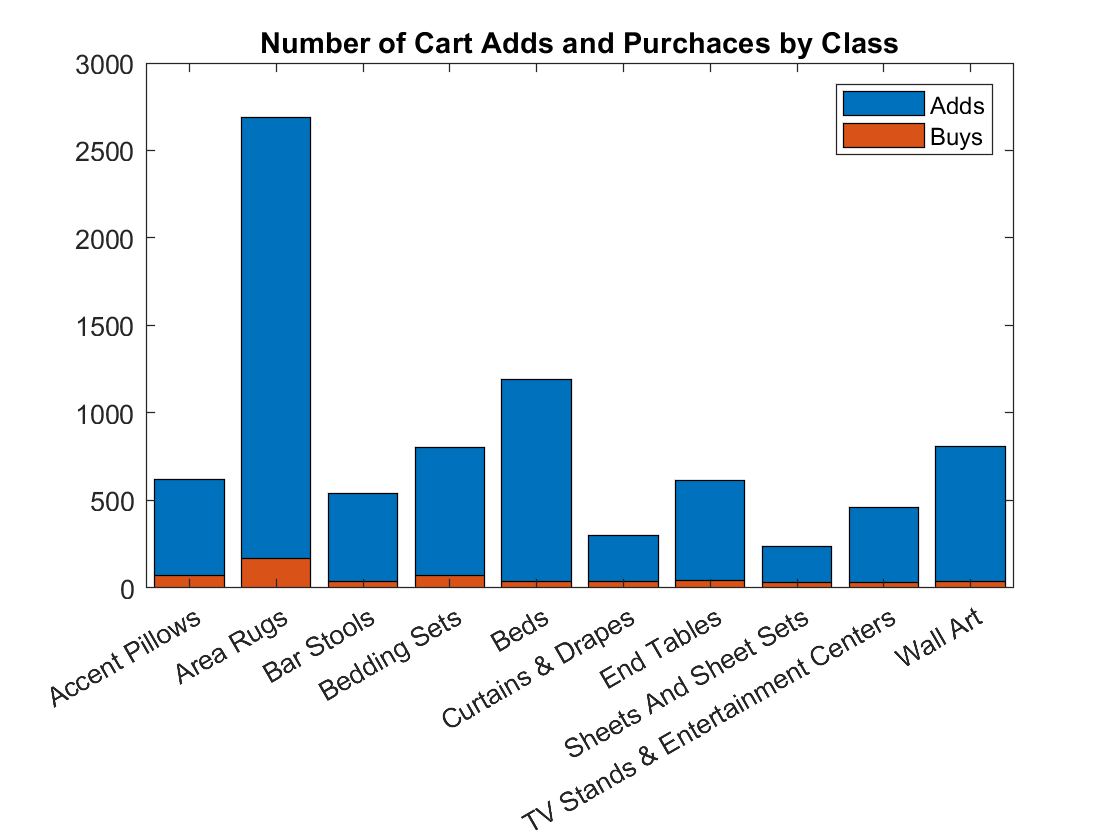

class2=categorical(class2);
class3=categorical(class3); 
figure(5);
bar(class2,add); 
hold on; 
bar(class3,buy);
hold off;
title("Number of Cart Adds and Purchaces by Class");
legend("Adds","Buys"); 

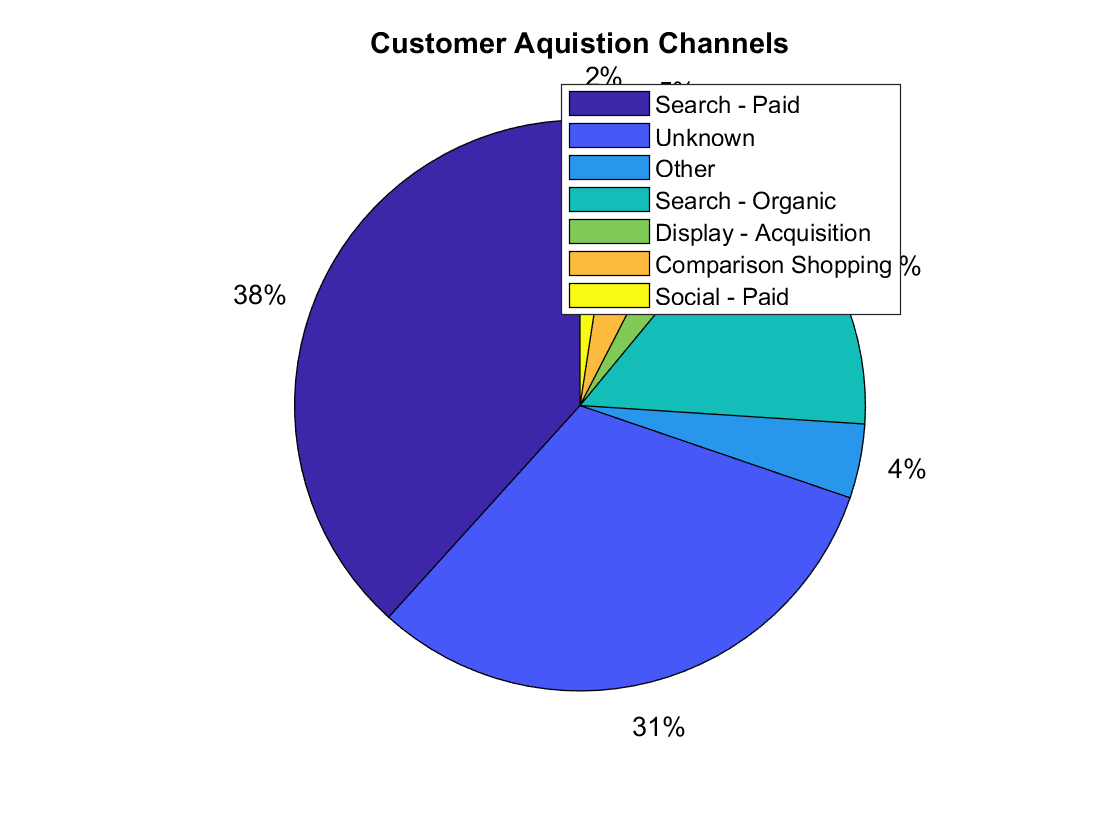

%find pie chart of customer aquistion 
x=table2cell(O); 
x(ismissing(O))={"Unknown"}; 
T = cell2table(x); 
O.CustomerId=T.x1; 
O.AcquisitionDate=T.x2;
O.AcquisitionChannel=T.x3; 
O.AcquisitionDevice=T.x4; 
tbl= cell2table(tabulate(O.AcquisitionChannel)) ; 
figure(6)
pie(tbl.Var2);
legend(tbl.Var1); 
title("Customer Aquistion Channels")

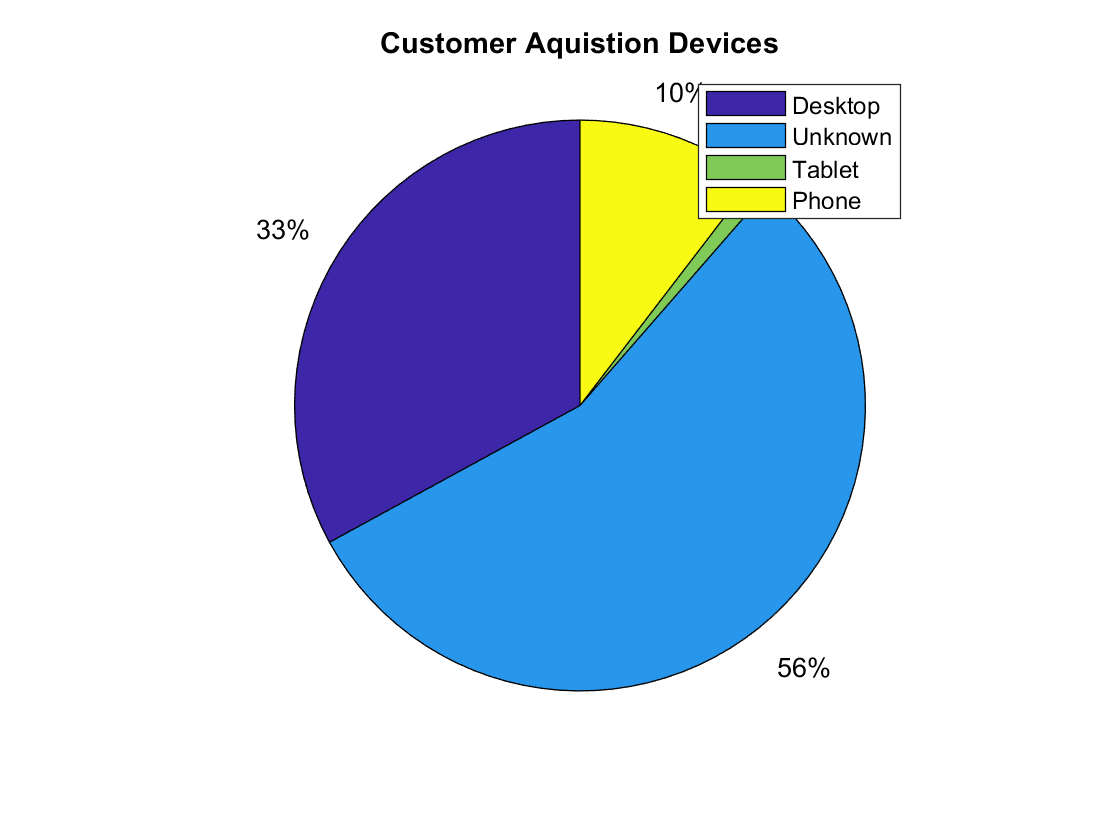


figure(7)
tbl= cell2table(tabulate(O.AcquisitionDevice)) ; 
pie(tbl.Var2);
legend(tbl.Var1); 
title("Customer Aquistion Devices")

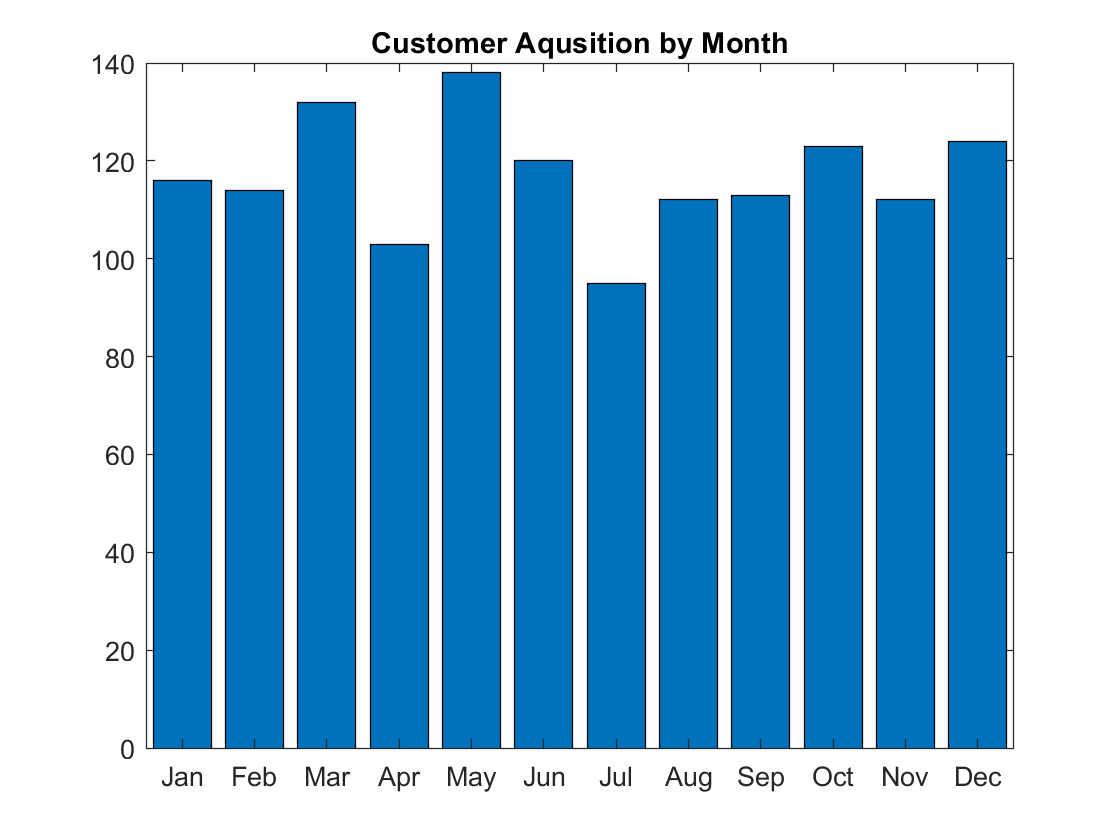

t=datetime(O.AcquisitionDate,"Format","dd-MMM-yyyy");
num_month=month(t);
for i=1:12
    freqmonth(i)=sum( num_month==i);
  
end
figure(8)
b=["Jan","Feb","Mar","Apr","May","Jun","Jul","Aug","Sep","Oct","Nov","Dec"];
A=categorical(b);
B = reordercats(A,b);
bar(B,freqmonth);
title("Customer Aqusition by Month");